# Analizando la Deforestación en la Selva Amazónica

Este ejemplo calcula el cambio en el área deforestada de una región en el Bosque Nacional Jamanxim en Brasil. Se utilizan cinco imágenes de esta región tomadas cada cuatro años: 2000, 2004, 2008, 2012 y 2016.

Estas imágenes son cortesía del [NASA Earth Observatory](https://earthobservatory.nasa.gov/images/145988/tracking-amazon-deforestation-from-above).

Para más detalles, explora el video *Introducción al procesamiento de imágenes para análisis de cambio climático con MATLAB *en el canal de* MATLAB en Español*.

Copyright 2022 The MathWorks, Inc.

## Tarea 1: Cargar imágenes y explorarlas

El primer paso es revisar las imágenes e identificar una que podamos usar para crear un prototipo de nuestro algoritmo. Podemos usar la aplicación [Image Browser app](matlab:imageBrowser("Data")) para ver rápidamente todas las imágenes y elegir una. Una vez que encontramos la imagen, la seleccionamos usando la función [*imread*](https://www.mathworks.com/help/matlab/ref/imread.html).

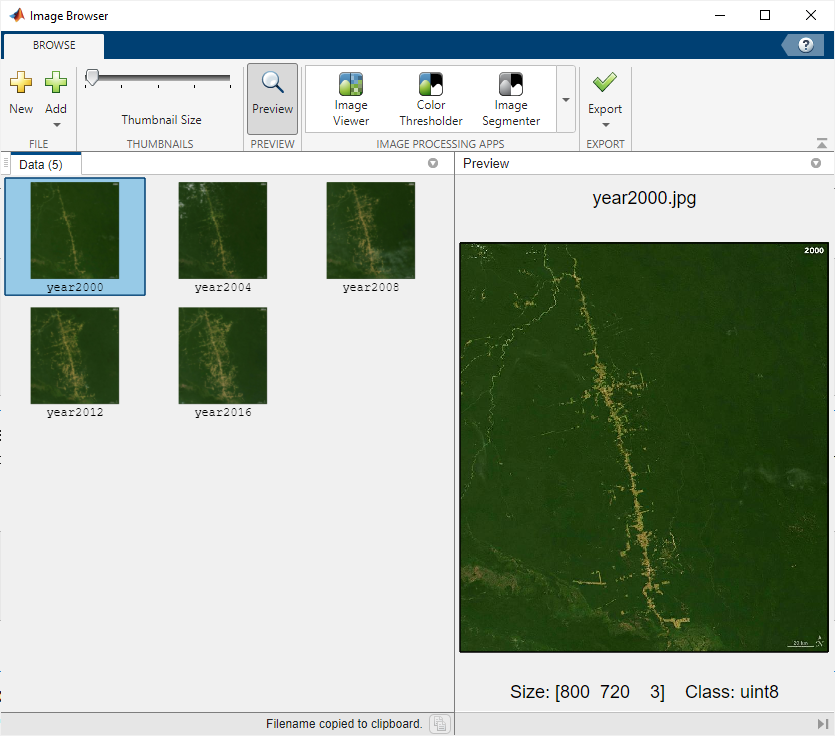

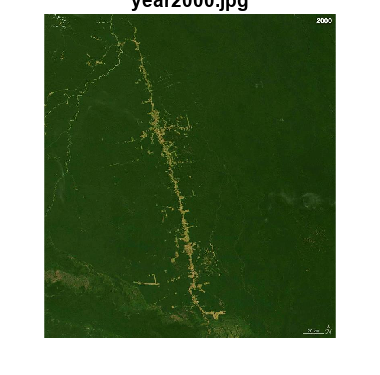

imageFileName = "year2000.jpg";
imageSelected = imread(fullfile("Data",imageFileName));
imshow(imageSelected)
title(imageFileName)

## Tarea 2: Aislar la región deforestada

El siguiente paso es aislar o segmentar la región deforestada en la imagen para calcular el área que cubre y compararla con otros resultados de diferentes años. Hacemos esto probando diferentes enfoques de segmentación en la imagen seleccionada para encontrar uno que funcione mejor.

### Tarea 2a: Segmentación basada en la intensidad

El primer enfoque que utilizamos es la segmentación de imágenes basada en la intensidad. Esto segmenta las regiones según el brillo o la intensidad de los píxeles individuales por encima de un umbral.

Primero debemos hacer un preprocesamiento para que las imágenes sean adecuadas para esto. Comenzamos convirtiendo la imagen RGB a una imagen en escala de grises usando la función [*im2gray*](https://www.mathworks.com/help/matlab/ref/im2gray.html).

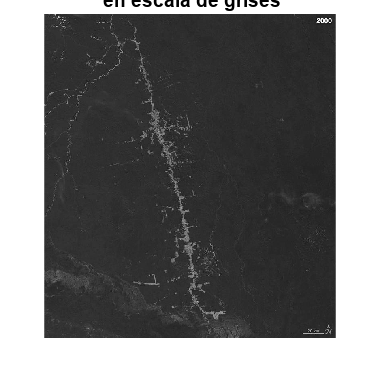

graySelected = im2gray(imageSelected);
imshow(graySelected)
title({imageFileName," en escala de grises"})

Al mirar el histograma de la intensidad de la imagen, vemos que la intensidad está agrupada. Podemos usar [*imadjust*](https://www.mathworks.com/help/images/ref/imadjust.html) para ajustar la intensidad para que sea más prominente.

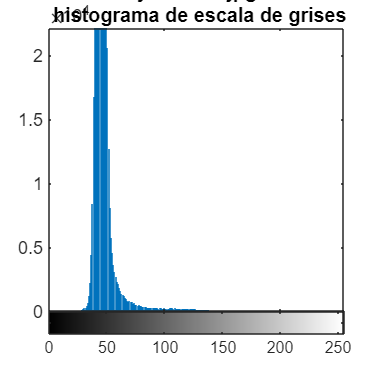

imhist(graySelected)
title({imageFileName," histograma de escala de grises"})

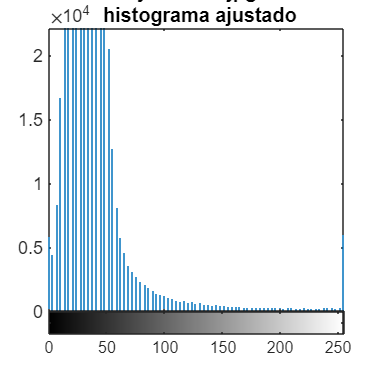

adjSelected = imadjust(graySelected);
imhist(adjSelected)
title({imageFileName," histograma ajustado"})

El siguiente código compara la imagen antes y después de ajustar la intensidad.

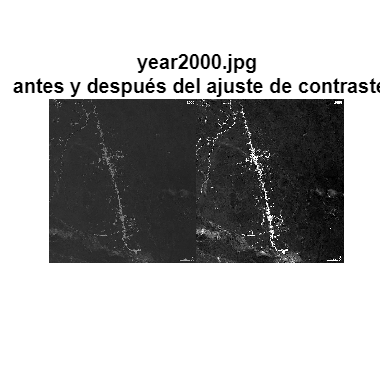

imshowpair(graySelected,adjSelected,"montage")
title({imageFileName," antes y después del ajuste de contraste"})

Con el preprocesamiento completo, cargamos la imagen ajustada en la aplicación [Image Segmenter app](matlab: imageSegmenter(adjSelected)). La aplicación también puede ajustar la intensidad internamente si cargamos las imágenes en escala de grises y no necesita que hagamos [*imadjust*](https://www.mathworks.com/help/images/ref/imadjust.html). En la aplicación, usamos la opción *Threshold* para crear una máscara que segmenta los píxeles que son más brillantes que un valor de umbral. Usando la opción de *manual threshold*, establecemos el nivel de umbral en 200 para segmentar las regiones más oscuras.

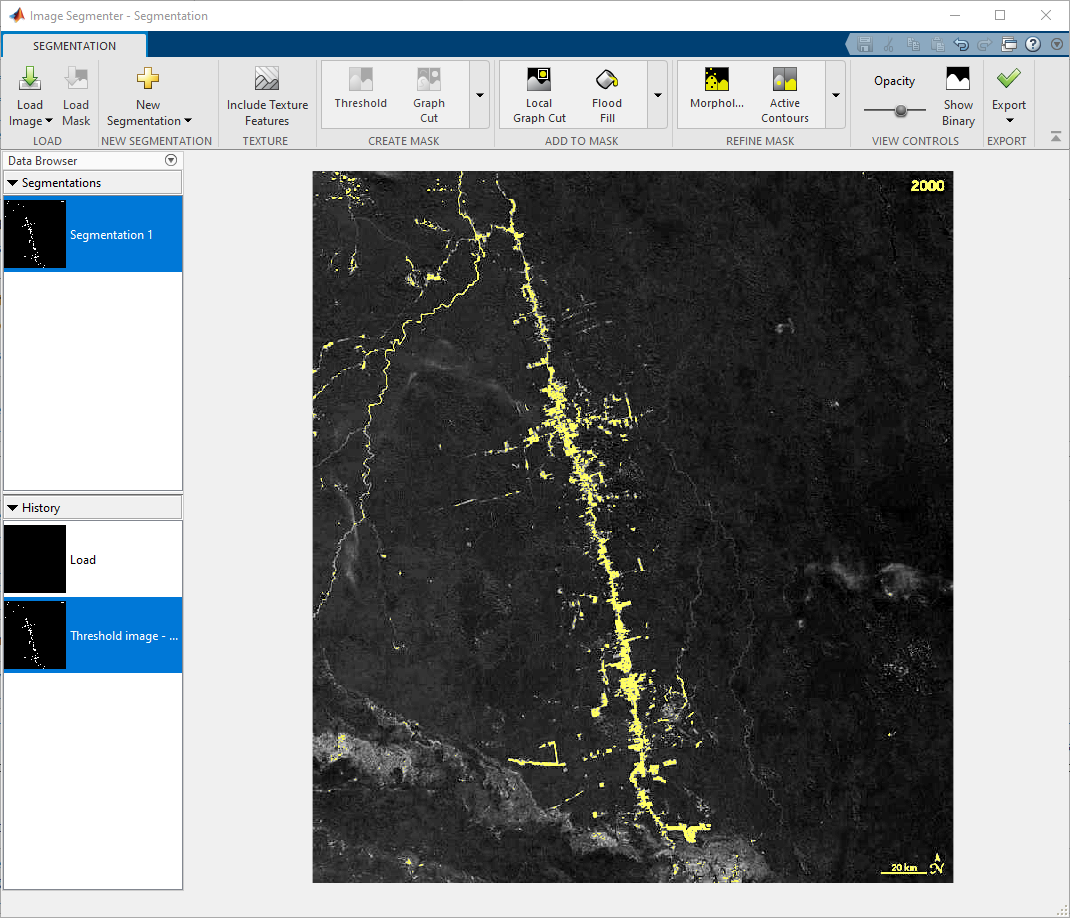

El enfoque utilizado para segmentar el área deforestada se puede exportar y guardar como una función que se ejecuta a continuación.

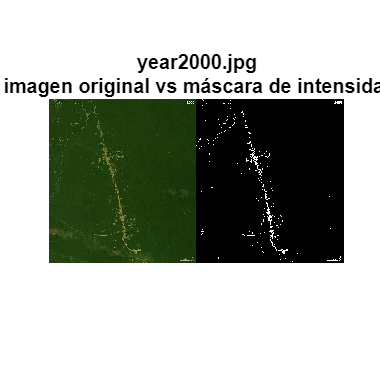

segmentMaskIntensity = segmentDeforestationIntensity(adjSelected);
imshowpair(imageSelected,segmentMaskIntensity,"montage")
title({imageFileName," imagen original vs máscara de intensidad"})

Para probar este enfoque en una imagen diferente, puede seleccionar una imagen diferente, preprocesarla y cargarla en la aplicación.

Si bien este enfoque funciona, también selecciona el texto en la parte superior e inferior derecha de las imágenes y el río a la izquierda. En otras imágenes con nubes, también incluye las nubes en la máscara.

### Tarea 2b: Segmentación basada en colores

Un segundo enfoque es segmentar el área deforestada utilizando las diferencias de color. Mirando la imagen, el área deforestada tiene un color marrón distintivo mientras que el fondo se ve verde y el río y las nubes se ven blancos.

Podemos cargar la imagen en color original en la aplicación [Color Thresholder app](matlab: colorThresholder(imageSelected)). La aplicación nos permite segmentar la imagen en función de múltiples espacios de color. Probar el espacio de color RGB segmenta la mayor parte del bosque pero aún deja algunas áreas no deseadas, el río y el texto. El espacio de color HSV nos da mejores resultados.

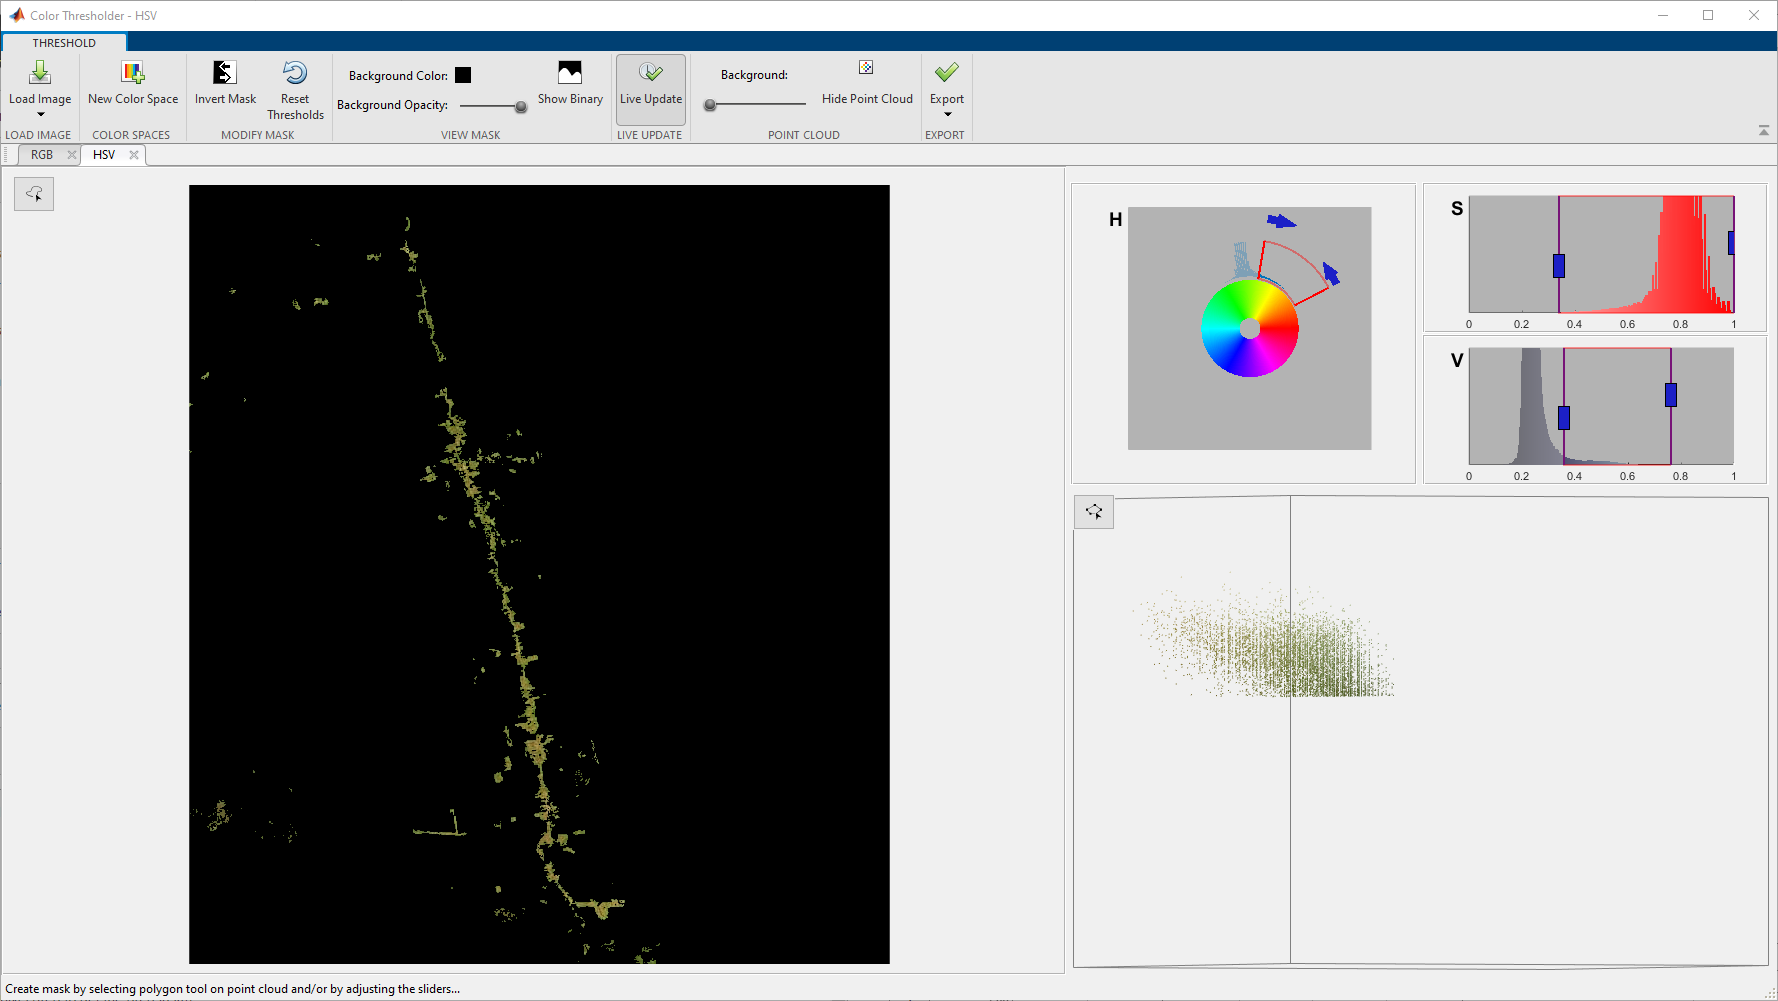

Exportamos y guardamos el código como una función, y lo ejecutamos a continuación.

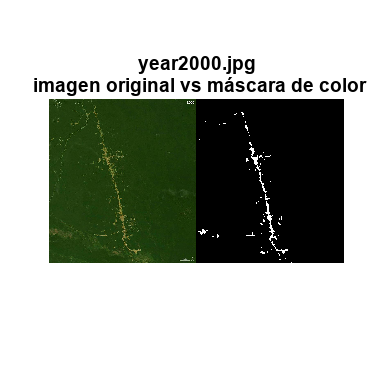

segmentMaskColor = segmentDeforestationColor(imageSelected);
imshowpair(imageSelected,segmentMaskColor,"montage")
title({imageFileName," imagen original vs máscara de color"})

## Tarea 3: Calcular el área

Ahora que tenemos la máscara de imagen que contiene el área deforestada, podemos calcular el área deforestada. Para ello, seleccionamos la máscara que queremos utilizar.

segmentMask = segmentMaskColor;

Calculamos el área de píxeles que cubren el área deforestada usando la función [*regionprops*](https://www.mathworks.com/help/images/ref/regionprops.html) . La función calcula varias propiedades para la máscara, pero estamos interesados en el parámetro de área para calcular el área de píxeles.

segmentMaskProps = regionprops("table",segmentMask,"all")

segmentMaskProps = 80×30 table
    Area        Centroid                  BoundingBox                                                                                                                                     SubarrayIdx                                                                                                                          MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage      ConvexArea    Circularity         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList       PixelLis

areaPixels = sum(segmentMaskProps.Area)

areaPixels = 10411

Una vez que tenemos el área de píxeles, podemos convertirla a km cuadrados usando la escala de la imagen. Cargamos la imagen en la aplicación [Image Viewer app](matlab: imtool(imageSelected)) y usamos la herramienta de medición para medir la longitud de la escala en píxeles.

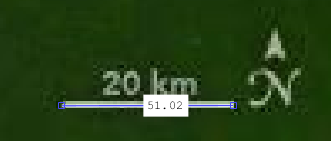

Usamos esta proporción para calcular cuántos kilómetros cuadrados componen cada píxel y lo multiplicamos por el área del píxel para obtener el área en kilómetros.

px2km = (20/51)^2

px2km = 0.1538

areaKmSq = round(areaPixels*px2km)

areaKmSq = 1601

## Tarea 4: Procesar imágenes por lotes

Ahora que tenemos un enfoque utilizable, podemos aplicar el enfoque basado en el umbral de color a todas las imágenes.

Creamos una función con el enfoque que queremos tomar y la guardamos como `computeArea.m`.

type calculateArea

function results = calculateArea(I)

% Segment
segmentMask = segmentDeforestationColor(I);

% Area in pixels
segmentMaskProps = regionprops("table",segmentMask,"Area");
areaPixels = sum(segmentMaskProps.Area);

% Area in km^2
px2km = (20/51)^2;
areaKmSq = round(areaPixels*px2km);

% Format into structure
results.segmentMask = segmentMask;
results.areaKmSq = areaKmSq;


Abrimos la [Image Batch Processor app ](matlab: imageBatchProcessor)y cargamos las imágenes. A continuación, seleccionamos la función de cálculo de área para usar en todas las imágenes y procesarlas. Puede ver los resultados de todas las imágenes. Los datos de areaKmSq se guardan como una tabla en `deforestationAllResults`.

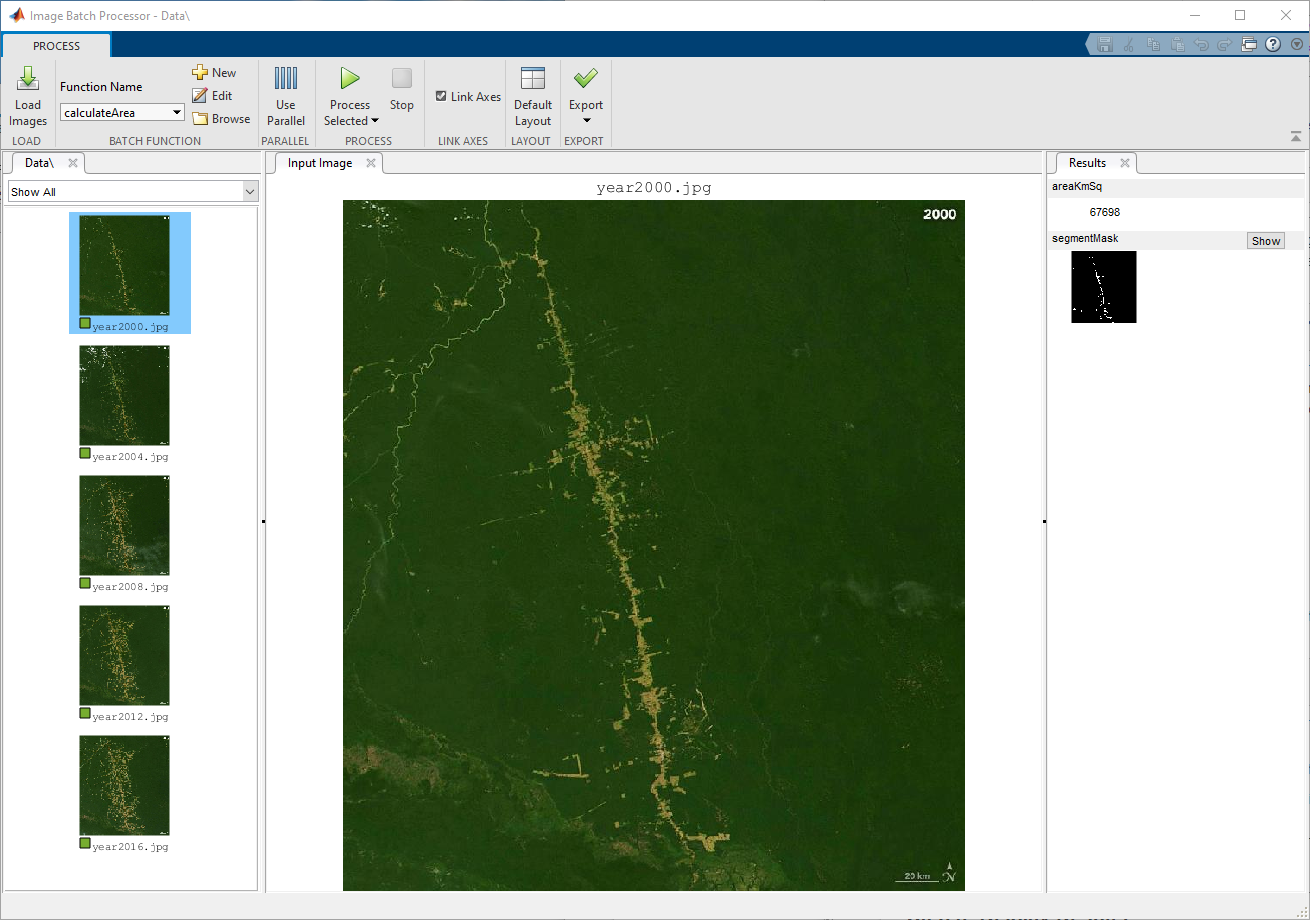

## Tarea 5: Mostrar resultados

Aquí mostramos los resultados generados como un montaje del mapa de segmentación y un gráfico de barras.

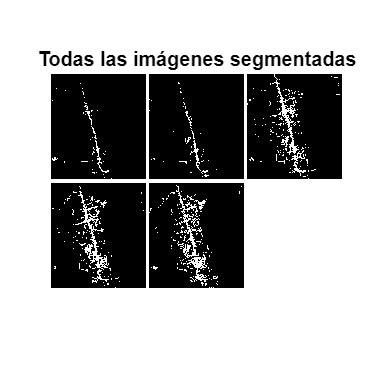

load(fullfile("Data","deforestationAllResults.mat"))

segmentedImages = deforestationAllResults.segmentMask;
montage(segmentedImages,...
    "BackgroundColor","White",...
    "BorderSize",5)
title("Todas las imágenes segmentadas")

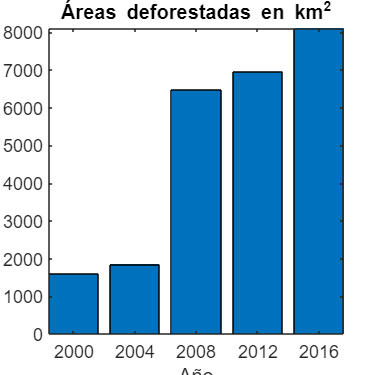


years = 2000:4:2016;
areas = deforestationAllResults.areaKmSq;
bar(years,areas)
title("Áreas deforestadas en km^{2}")
xlabel("Año")
ylabel("km^{2}")
axis tight

## Aplicaciones de procesamiento de imágenes y visión artificial

Esta demostración utiliza algunas de las aplicaciones de Image Processing Toolbox y Computer Vision Toolbox. Aquí encontrará una lista de todas las aplicaciones en los toolboxes, incluyendo algunas que no vimos hoy.

- [Image Browser App](matlab:doc('imageBrowser')) / [Image Viewer App](matlab:doc('imtool')) 

- [Color Thresholder App](matlab:doc('colorThresholder'))

- [Image Region Analyzer App](matlab:doc('imageRegionAnalyzer'))

- [Image Segmenter App](matlab:doc('imageSegmenter'))

- [Image Batch Processor App](matlab:doc('imageBatchProcessor'))

Copyright 2022 The MathWorks, Inc.